# Create Live Script with Multiple Interactive Controls

This example shows how you can use interactive controls to visualize and investigate patient data in MATLAB®. The example plots the height versus the weight of either male or female patients, and highlights the patients over a specified height and weight.

To specify the gender of the patients to plot, insert a drop-down list and select the `genderStrings` variable to populate the items in the list. To specify a threshold height and weight, insert two numeric sliders and select the `minHeight`, `maxHeight`, `minWeight`, and `maxWeight` variables as the **Min** and **Max** values. 

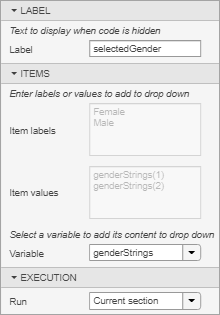 

To view and interact with the controls, open this example in your browser or in MATLAB. 

load patients
genderStrings = ["Female","Male"];

selectedGender = genderStrings(2);
minHeight = min(Height);
maxHeight = max(Height);
minWeight = min(Weight);
maxWeight = max(Weight);

thresholdHeight = 68;
thresholdWeight = 132;

overThresholdWeights = Weight(Gender==selectedGender & Weight>=thresholdWeight & Height>=thresholdHeight);
overThresholdHeights = Height(Gender==selectedGender & Weight>=thresholdWeight & Height>=thresholdHeight);

sp1 = scatter(Height(Gender==selectedGender),Weight(Gender==selectedGender),'blue');
hold on

sp2 = scatter(overThresholdHeights, overThresholdWeights,'red');
hold off

title('Height vs. Weight of ' + selectedGender + ' Patients')

legendText = sprintf('Patients over %d inches and %d pounds.',thresholdHeight,thresholdWeight);
legend(sp2,legendText,'Location','southoutside')

*Copyright 2018 The MathWorks, Inc.*